# DSP Pipeline Analysis

Program to plot the outputs from the local processing on the SHARC Buoy. 

%Specify location of file
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";

%Specify variables
opts = delimitedTextImportOptions("NumVariables", 1);
opts.VariableNames = ["Heave"];
opts.VariableTypes = ["double"];

%Read in table
wavefile = fullfile(outdir_2, "SHARC_Displacement_Window.txt");
WaveTable = readtable(wavefile, opts);

## Plot raw acceleration data

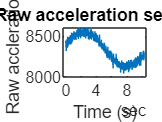

Fs = 100;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, WaveTimeTable.Heave);
xlabel("Time (s)");
ylabel("Raw accleration");
title("Raw acceleration segment");

## Plot scaled data

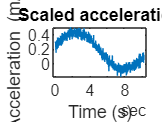

Fs = 100;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, WaveTimeTable.Heave);
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");
title("Scaled acceleration");

##  Plot detrended data

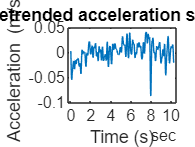

Fs = 100;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, lowpass(WaveTimeTable.Heave, 2, Fs));
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");
title("Detrended acceleration segment");

##  Plot LPF + Decimated data

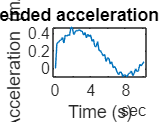

Fs = 6.25;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, WaveTimeTable.Heave);
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");
title("Detrended acceleration segment");

##  Plot Concatenated Data

Fs = 6.25;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, lowpass(WaveTimeTable.Heave, 10, Fs));

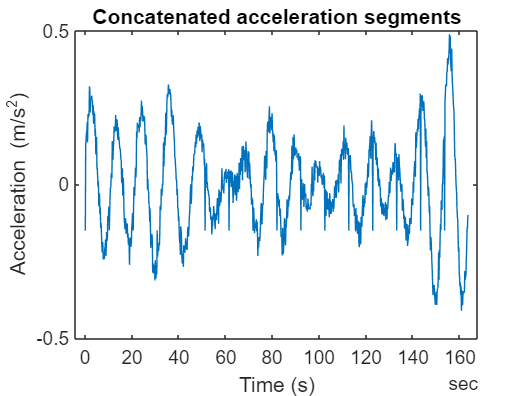

xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");
title("Concatenated acceleration segments");

##  Plot FFT Data


Fs = 3.25; %104/16; %6.25; 
Nfft = 1024; 
f = Fs*(-Nfft/2:1:Nfft/2-1)'./Nfft

f =    -1.6250
   -1.6218
   -1.6187
   -1.6155
   -1.6123
   -1.6091
   -1.6060
   -1.6028
   -1.5996
   -1.5964


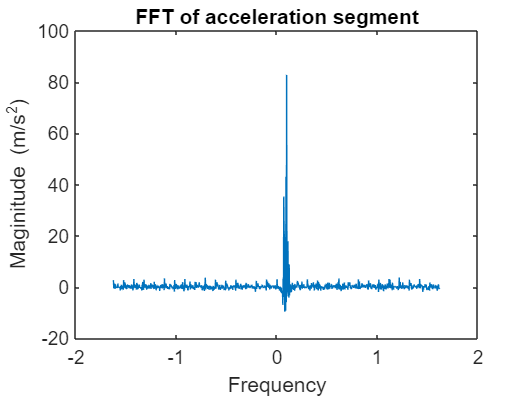


WaveFFT = WaveTable.Heave;
plot(f, -1*fftshift(WaveFFT));
xlabel("Frequency");
ylabel("Maginitude (m/s^2)");
title("FFT of acceleration segment");

##  Plot Displacement Data

Fs = 6.25;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, -1*lowpass(WaveTimeTable.Heave, 10, Fs));

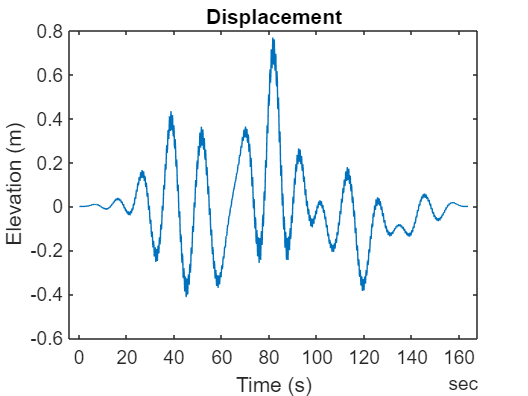

xlabel("Time (s)");
ylabel("Elevation (m)");
title("Displacement");